Loads traces

load('../dat/Kruppel_eve2_pass1/inference_traces_Kruppel_eve2_pass1_dT20.mat');

View traces

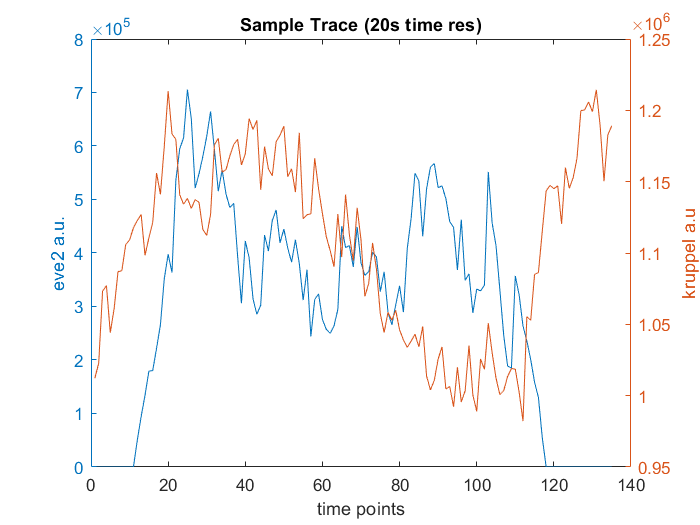

i = 280;
figure();
yyaxis left
plot(trace_struct_final(i).fluo_interp);
ylabel('eve2 a.u.')
yyaxis right
plot(trace_struct_final(i).protein_interp);
ylabel('kruppel a.u');
xlabel('time points');
title('Sample Trace (20s time res)')

Looks at histogram of ap position shifts for each set

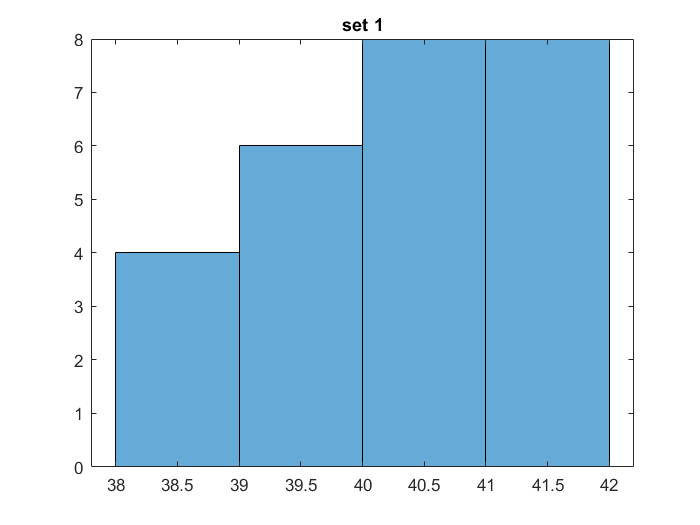

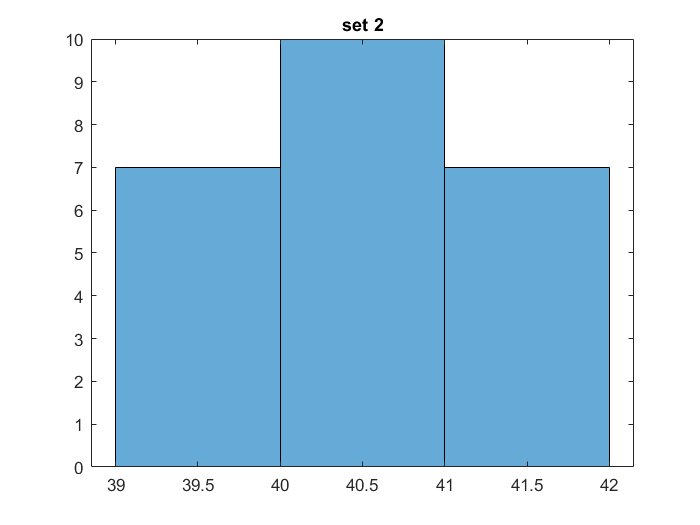

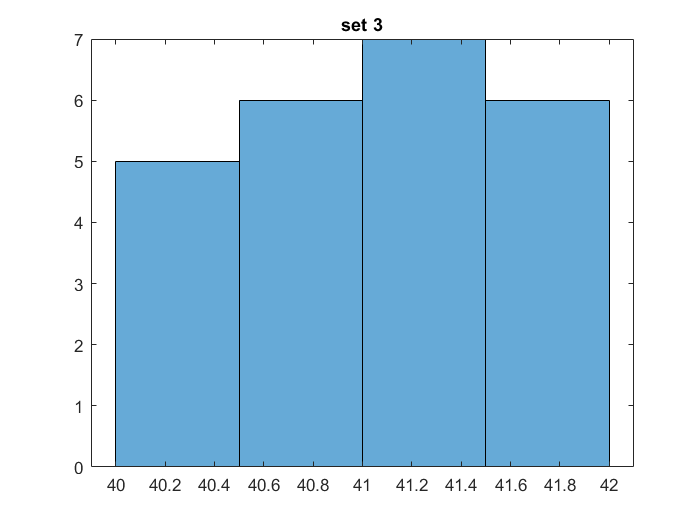

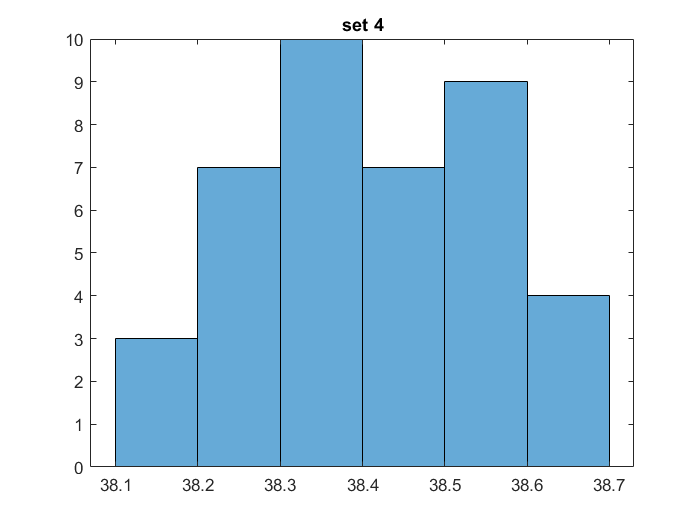

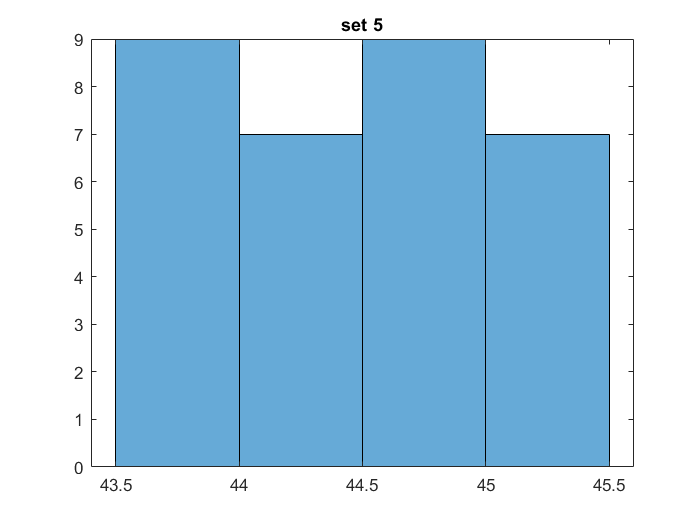

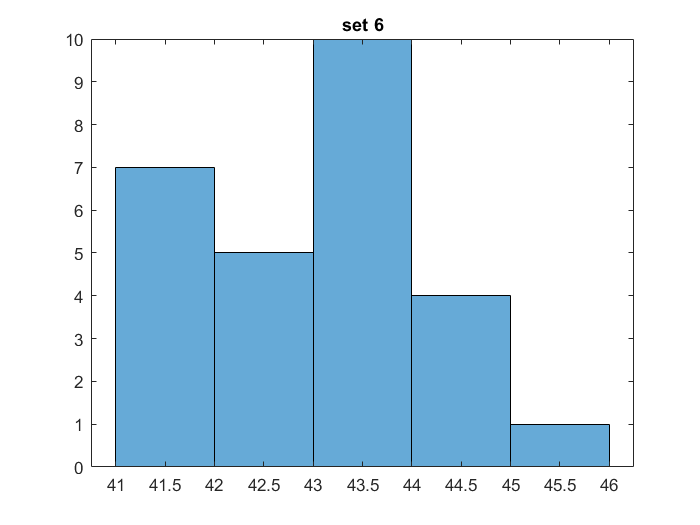

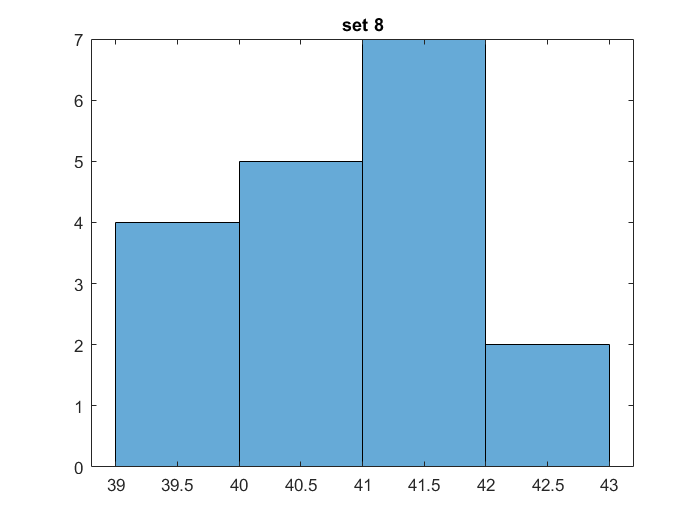

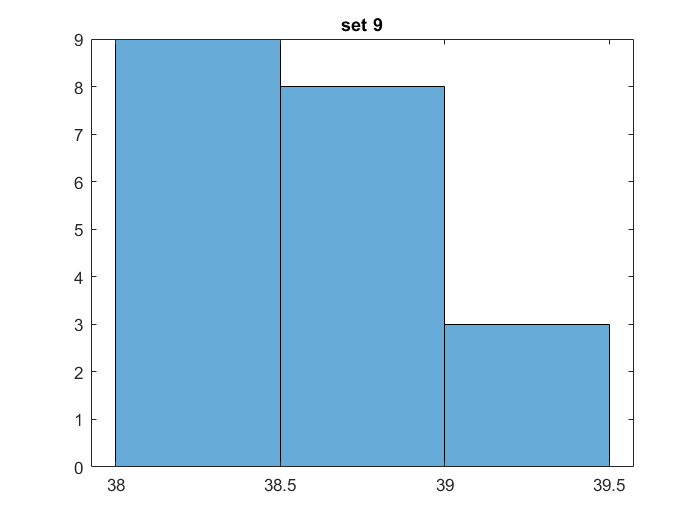

sets_to_use = [1:6 8:12];
for set = sets_to_use
    set_struct = trace_struct_final([trace_struct_final.setID] == set);
    set_struct = set_struct(abs([set_struct.MeanAP]) < 1);
    AP_diff = [set_struct.MeanAPOrig] * 100 - [set_struct.MeanAP];
    figure();
    histogram(AP_diff);
    title(['set ' num2str(set)])
end